jemplo: Problema de mínimos cuadrados:

 Sea el siguiente conjunto de puntos (aleatorios) en el plano: (1,3), (2, -1), (4,7), (4.2,-3.5), (6,6) (8,8)

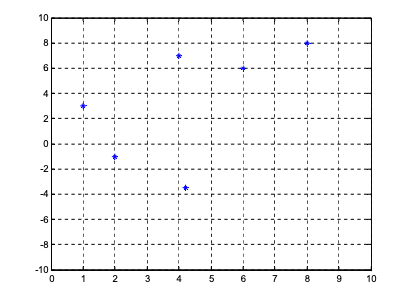

Queremos encontrar una función, de algún tipo predefinido, que pase lo mas cerca posible de esos puntos; Por ejemplo, un polinomio de grado 3: P3(x)= ax3+bx2+cx+d

Para cada punto planteamos la igualdad “deseada”: 

        para (1,3): a·13+b·12+c·1+d = 3

        para (2,-1): a·23+b·22+c·2+d = -1 

        para (4,7): a·43+b·42+c·4+d = 7 

        Y así para todos los puntos

versión Matricial

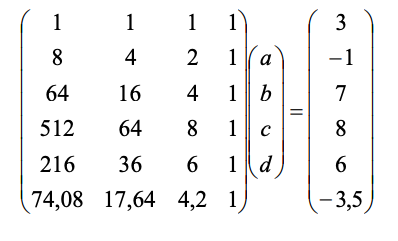


A=[    1     1     1   1
       8     4     2   1
      64    16     4   1
     512    64     8   1 
     216    36     6   1 
    74.08  17.64  4.2  1 ]

A =     1.0000    1.0000    1.0000    1.0000
    8.0000    4.0000    2.0000    1.0000
   64.0000   16.0000    4.0000    1.0000
  512.0000   64.0000    8.0000    1.0000
  216.0000   36.0000    6.0000    1.0000
   74.0800   17.6400    4.2000    1.0000


%det(A)
rank(A)

ans = 4


b= [ 3 -1 7 8 6 -3.5]';
%Resolución mediante las ecuaciones normales
sol=A'*A\A'*b

sol =    -0.1286
    1.9746
   -7.6197
    8.3793


%Resolución mediante la QR

[Q ,R]=qr(A) % descomposición QR

Q =    -0.0018   -0.0620    0.5609    0.7647   -0.2769    0.1418
   -0.0142   -0.2094    0.6703   -0.2356    0.6069   -0.2877
   -0.1134   -0.5286    0.1280   -0.2899   -0.6457   -0.4363
   -0.9073    0.3573    0.1507   -0.1254   -0.0858    0.0576
   -0.3828   -0.4941   -0.4407    0.4622    0.3589   -0.2695
   -0.1313   -0.5487    0.0525   -0.2152    0.0426    0.7942


R =  -564.3127  -76.0354  -10.5901   -1.5507
         0  -13.9564   -5.0059   -1.4855
         0         0    1.1961    1.1218
         0         0         0    0.3608
         0         0         0         0
         0         0         0         0



b1=Q'*b  % modificación b

b1 =    -9.8805
   -1.8621
    0.2863
    3.0235
   -4.6397
   -6.2775


sol1= R(1:4,:)\b1(1:4)

sol1 =    -0.1286
    1.9746
   -7.6197
    8.3793


Ahora representamos el polinomio: sol1(1) x^3 + sol1(2) x^2  +sol1(3) x + sol1(4)

x=linspace (0, 10), 

x =          0    0.1010    0.2020    0.3030    0.4040    0.5051    0.6061    0.7071    0.8081    0.9091    1.0101    1.1111    1.2121    1.3131    1.4141    1.5152    1.6162    1.7172    1.8182    1.9192    2.0202    2.1212    2.2222    2.3232    2.4242    2.5253    2.6263    2.7273    2.8283    2.9293    3.0303    3.1313    3.2323    3.3333    3.4343    3.5354    3.6364    3.7374    3.8384    3.9394    4.0404    4.1414    4.2424    4.3434    4.4444    4.5455    4.6465    4.7475    4.8485    4.9495


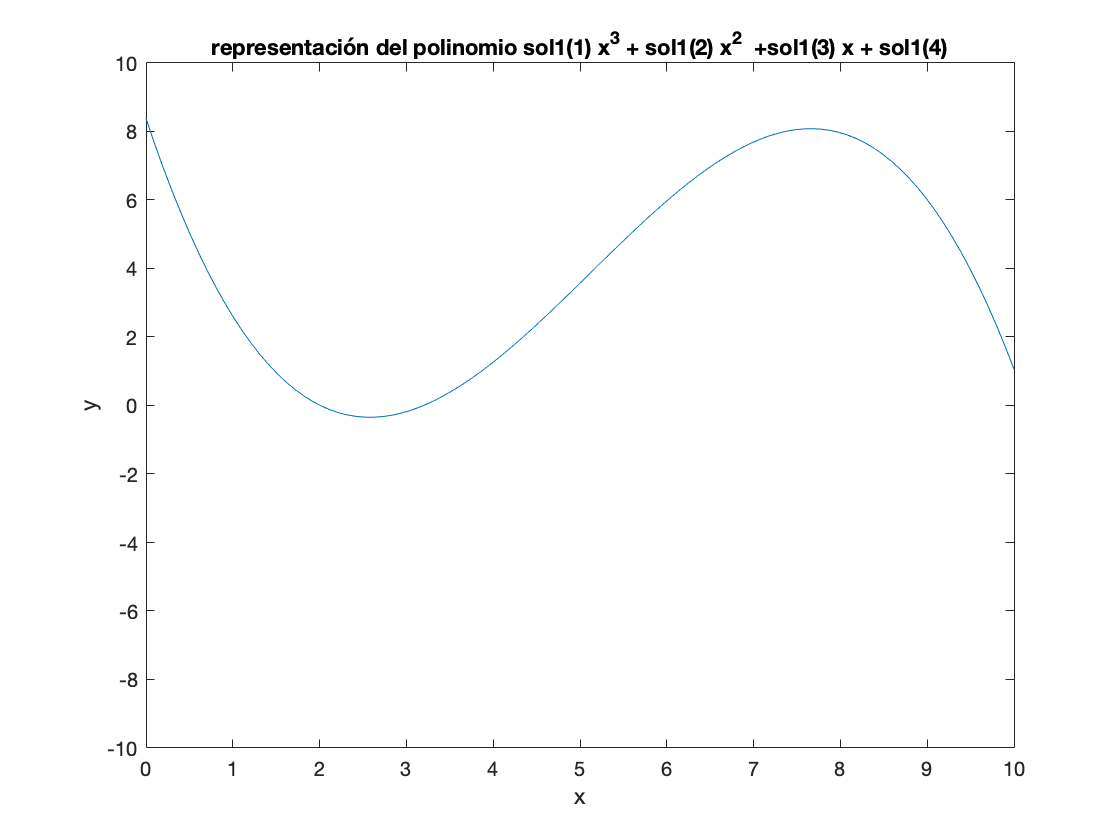

pol= polyval(sol1,x);figure,
 plot(x,pol); axis([0 10 -10 10]);
title('representación del polinomio sol1(1) x^3 + sol1(2) x^2  +sol1(3) x + sol1(4)')
xlabel('x'), ylabel ('y')

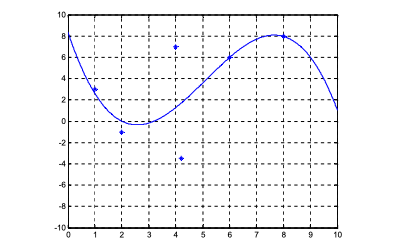

Residuo= norm(b1(rank(A)+1: size(A,1)))

Residuo = 7.8060